
clear all;
format long e
% Volume fraction
%Vf = 0.5;
syms Vf
Vm = 1.0 - Vf;
t = linspace(0,1,100);
% Now calculate the stiffness matrix of fibre
% Fibre is transversely isotropic with following properties in GPa
E1 = 80;
E2 = 80;
E3 = E2;
%
G12 = 33.33;
G13 = 33.33;
%
G23 = 33.33;
%
nu_12 = 0.2;
nu_13 = nu_12;
%
nu_23 = E2/(2.0 * G23) - 1.0;
%
nu_21 = nu_12 * E2/E1;
nu_31 = nu_13 * E3/E1;
nu_32 = nu_23 * E3/E2;
% Initialization
s = zeros(6,6);
Cf = zeros(6,6);
Cm = zeros(6,6);
%
s(1,1)=1.0/E1;
s(2,2)=1.0/E2;
s(3,3)=1.0/E3;
%
s(1,2)=-nu_21/E2;
s(1,3)=-nu_31/E3;
%
s(2,1)=-nu_21/E2;
s(2,3)=-nu_32/E3;
%
s(3,1)=-nu_13/E1;
s(3,2)=-nu_23/E2;
% Following order is according order in Abaqus
s(4,4)=1.0/G12;
s(5,5)=1.0/G13;
s(6,6)=1.0/G23;
Cf = inv(s)

Cf =      8.889037076553748e+01     2.222592691384369e+01     2.222592691384370e+01                         0                         0                         0
     2.222592691384369e+01     8.889481728460922e+01     2.223481728460923e+01                         0                         0                         0
     2.222592691384370e+01     2.223481728460923e+01     8.889481728460923e+01                         0                         0                         0
                         0                         0                         0     3.333000000000000e+01                         0                         0
                         0                         0                         0                         0     3.333000000000000e+01                         0
                         0                         0                         0                         0                         0     3.333000000000000e+01


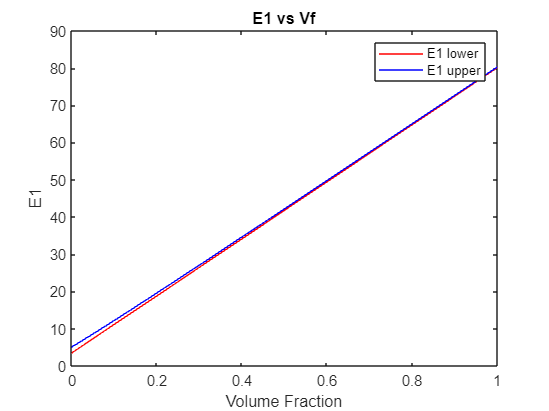

% Calculate the stiffness matrix of matrix
% Matrix is isotropic with following properties
E0 = 3.35;
XNU = 0.35;
%
XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
ZZ = E0 /(2.0 * (1.0 + XNU));
%
for I = 1:3
    for J = 1:3
        Cm(I,J) = YY;
    end
    Cm(I,I) = XX;
    Cm(I+3,I+3) = ZZ;
end
kf = (1/3)*(Cf(1,1)+2*Cf(1,2));
km = (1/3)*(Cm(1,1)+2*Cm(1,2));
Gm = ZZ;
G12;


E1_lower = E0*Vm + E1*Vf + (4*((XNU-nu_12)^2)*kf*km*Gm)/(km*kf + Gm*(Vf*kf + Vm*km));
E1_upper = E0*Vm + E1*Vf + (4*((nu_12-XNU)^2)*kf*km*G12)/(km*kf + G12*(Vf*kf + Vm*km));
E1_l= double(subs(E1_lower,Vf,t));
plot(t,E1_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("E1")
hold on
E1_u= double(subs(E1_upper,Vf,t));
plot(t,E1_u,'b','Linewidth',0.2);
title("E1 vs Vf")
legend(["E1 lower","E1 upper"])
hold off

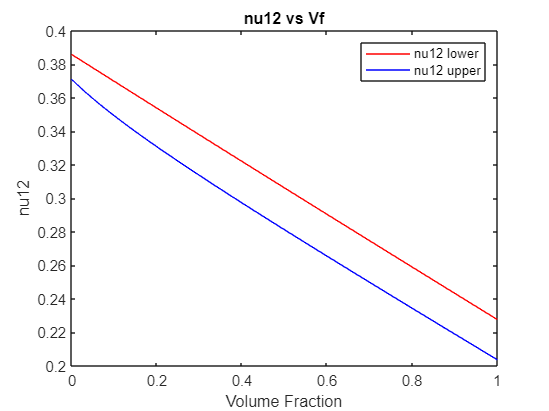




nu12_lower = XNU*Vm + nu_12*Vf + ((XNU-nu_12)*(kf-km))/(km*kf + Gm*(Vf*kf + Vm*km));
nu12_upper = XNU*Vm + nu_12*Vf + ((XNU-nu_12)*(kf-km))/(km*kf + G12*(Vf*kf + Vm*km));
nu12_l= double(subs(nu12_lower,Vf,t));
plot(t,nu12_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("nu12")
hold on
nu12_u= double(subs(nu12_upper,Vf,t));
plot(t,nu12_u,'b','Linewidth',0.2);
title("nu12 vs Vf")
legend(["nu12 lower","nu12 upper"])
hold off

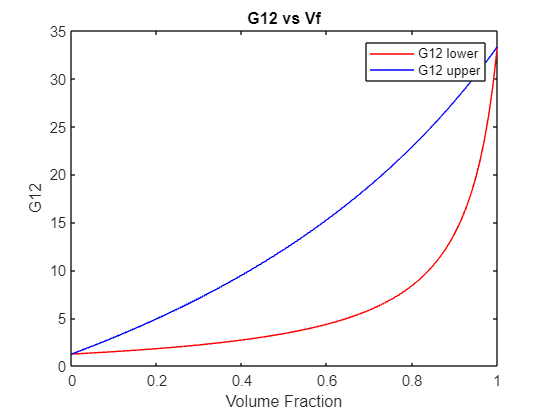




G12_lower = Gm*((G12+Gm)+Vf*(G12-Gm))/((G12+Gm)-Vf*(G12-Gm));
G12_upper = G12*((G12+Gm)-Vm*(G12-Gm))/((G12+Gm)+Vm*(G12-Gm));
G12_l= double(subs(G12_lower,Vf,t));
plot(t,G12_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("G12")
hold on
G12_u= double(subs(G12_upper,Vf,t));
plot(t,G12_u,'b','Linewidth',0.2);
title("G12 vs Vf")
legend(["G12 lower","G12 upper"])
hold off

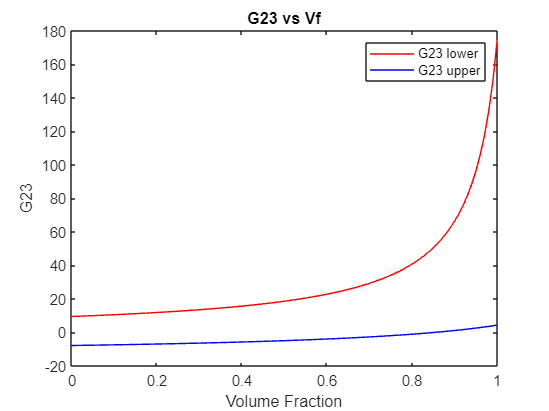




G23_lower = Gm*(kf*(G23+Gm)+Vf*km*(G23-Gm)+2*G23*Gm)/(km*(G23+Gm)-Vf*(G23-Gm)*(km+2*Gm)+2*G23*Gm);
G23_upper = G23*(km*(G23+Gm)-Vm*kf*(G23-Gm)+2*G23*Gm)/(kf*(G23+Gm)+Vm*(G23-Gm)*(kf+2*G23)+2*G23*Gm);
G23_l= double(subs(G23_lower,Vf,t));
plot(t,G23_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("G23")
hold on
G23_u= double(subs(G23_upper,Vf,t));
plot(t,G23_u,'b','Linewidth',0.2);
title("G23 vs Vf")
legend(["G23 lower","G23 upper"])
hold off



k_lower = (km*(kf+Gm)+Vf*Gm*(kf-km))/((kf+Gm)-Vf*(kf-km))

 
k_lower =
 
                     170.061443271017652 + 50.52939743 Vf
                 --------------------------------------------
                 45.6881489384823638 - 40.7251859755194019 Vf


k_upper = (kf*(km+G23)+Vm*G23*(km-kf))/((km+G23)-Vm*(km-kf))

 
k_upper =
 
                         289.504797 + 1357.370449 Vf
                     ------------------------------------
                     77.77740820 - 40.7251859755194019 Vf


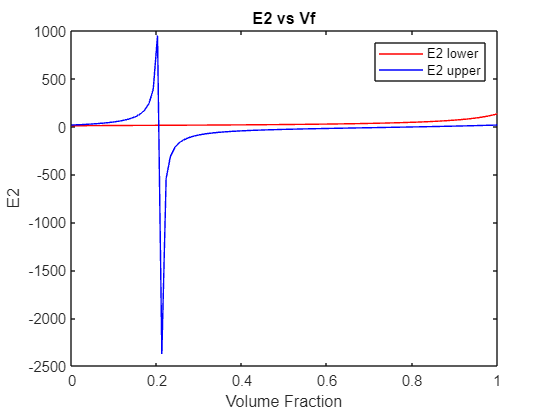


E2_lower = 1/((1/(4*G23_lower))+(1/(4*k_lower))+(nu12_upper^2/E1_lower));
E2_upper = 1/((1/(4*G23_upper))+(1/(4*k_upper))+(nu12_lower^2/E1_upper));
E2_l= double(subs(E2_lower,Vf,t));
plot(t,E2_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("E2")
hold on
E2_u= double(subs(E2_upper,Vf,t));
plot(t,E2_u,'b','Linewidth',0.2);
title("E2 vs Vf")
legend(["E2 lower","E2 upper"])
hold off

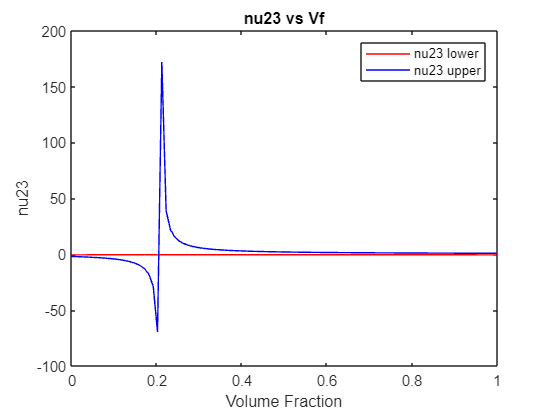



nu23_lower = (2*E1_lower*k_lower-E1_lower*E2_lower-4*(nu12_upper^2)*k_lower*E2_lower)/(2*E1_lower*k_lower);
nu23_upper = (2*E1_upper*k_upper-E1_upper*E2_upper-4*(nu12_lower^2)*k_upper*E2_upper)/(2*E1_upper*k_upper);
nu23_l= double(subs(nu23_lower,Vf,t));
plot(t,nu23_l,'r','Linewidth',0.2);
xlabel("Volume Fraction")
ylabel("nu23")
hold on
nu23_u= double(subs(nu23_upper,Vf,t));
plot(t,nu23_u,'b','Linewidth',0.2);
title("nu23 vs Vf")
legend(["nu23 lower","nu23 upper"])
hold off